# Doc: Assess local tuning biases in the mouse dLGN

- perhaps add something that is not the title of your paper, maybe the goal of the paper, or the significance sttament

- link abstract or complete manuscript/thesis

## Goals, Hypothesis and Analysis

The aim of the project is to assess the presence of 'local tuning biases' among populations of LGN afferents innervating the mouse primary visual cortex. 

From a computer vision point of view, we test the notion that neurons/units in the dLGN 'process' a  image regions with a similar, or biased, set of orientated filters. 

To answer this question,  

-  Estimate the spatial receptive fields and oriention tuning of populations of thalamic boutons innervating mouse V1. 

- then for each pair of boutons, determing how much their receptive fields overlap and how similar their tuning is

If LGN boutons with overlapping receptive fields have similar tuning profiles, this would suggest the presence of local tuning biases.

## Prepare Data Files

clear;
clc;
addpath /Users/luis/Box/prjLGNTB/lgnDATA/   
addpath /Users/luis/Box/prjLGNTB/lgnANALYSIS/
cd /Users/luis/Box/prjLGNTB/lgnANALYSIS


lgn = lgnanz;
lgn.uif_tbl_base

ans = 10×4 table
    uif    mouse_id      fname_base_ret      fname_base_orisf 
    ___    _________    _________________    _________________
     1     {'lgn02'}    {'lgn02_001_000'}    {'lgn02_001_001'}
     2     {'lgn02'}    {'lgn02_002_000'}    {'lgn02_002_002'}
     3     {'lgn02'}    {'lgn02_003_000'}    {'lgn02_003_001'}
     4     {'lgn03'}    {'lgn03_001_001'}    {'lgn03_001_000'}
     5     {'lgn03'}    {'lgn03_001_003'}    {'lgn03_001_002'}
     6     {'lgn03'}    {'lgn03_002_001'}    {'lgn03_002_000'}
     7     {'lgn04'}    {'lgn04_002_000'}    {'lgn04_002_003'}
     8     {'lgn05'}    {'lgn05_001_001'}    {'lgn05_001_000'}
     9     {'lgn05'}    {'lgn05_008_001'}    {'lgn05_008_000'}
    10     {'lgn05'}    {'lgn05_011_000'}    {'lgn05_011_001'}

these are all the unique  fields that were imaged. 9 total imaging sessions were conducted, from 4 different mice.

# Asess the properties of individual LGN boutons innervating mouse V1

## Load the 'roi' (LGN bouton) data table 

Here we  load an a table of ROI's. 

- rows correspond to a lgn bouton in some imaging field

- columns correspond some property of that bouton. These properties include: imaging field ID, tuning kernel, retinotpoic kernel, orientation preference, spatial frequency preference, etc

- note that some rois have both tuning kernels AND receptive fields, while some have only one but not the other. This analysis only considers boutons with BOTH types of kernels

**Start Generating table...**

first look at which imaging fields are available for processing...

lgn.all_available_uif'

ans =      1     2     3     4     5     6     7     8     9    10


Select your imaging fields

% uifs_to_process = [3 4];
uifs_to_process = lgn.all_available_uif([1,2])

uifs_to_process =      1
     2


Generate The Table...

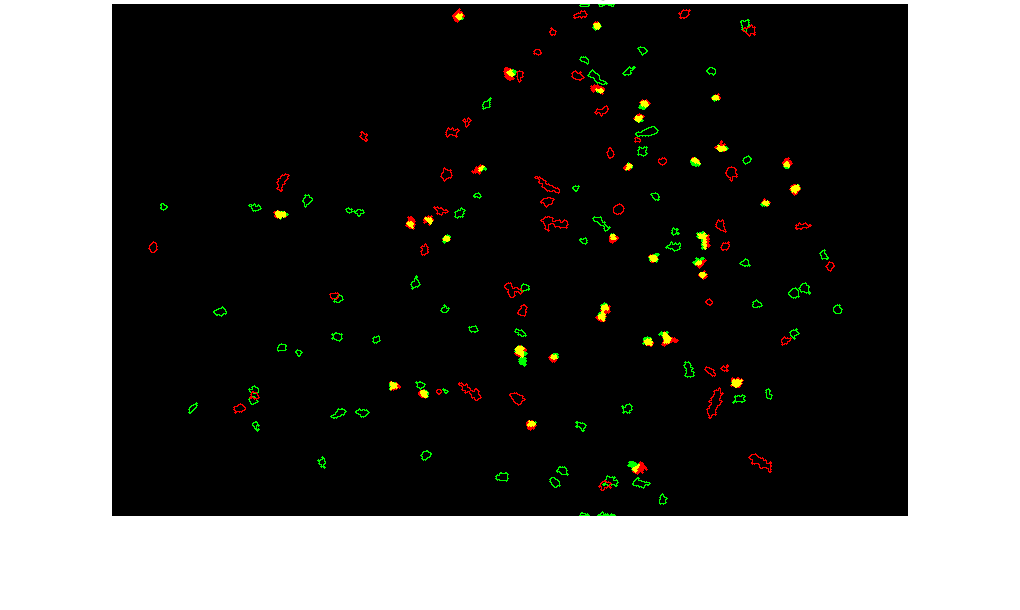

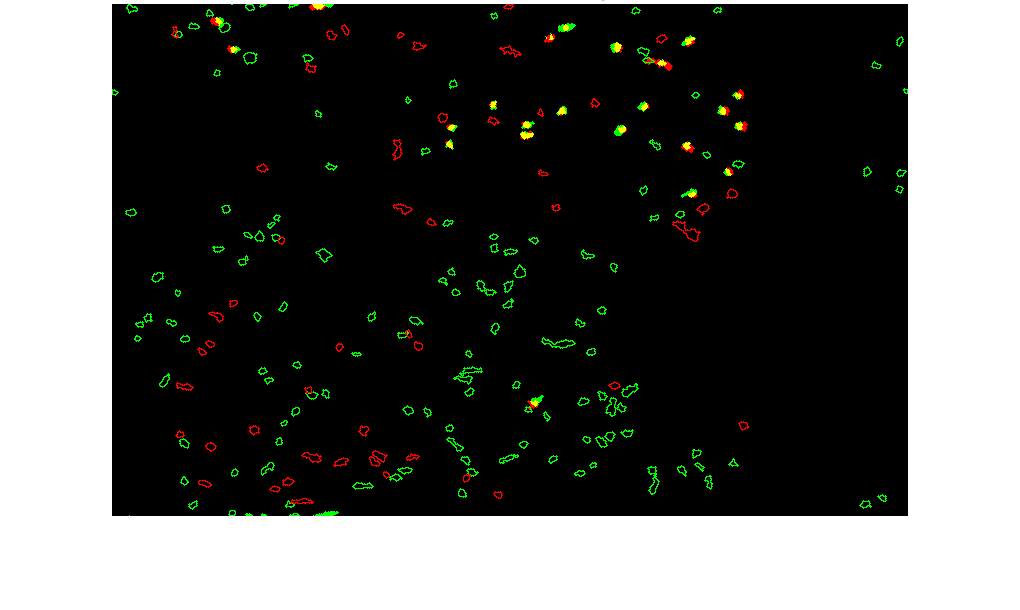

lgn.get_roi_tables(uifs_to_process);

## Description of the table

Make sure the imaging fields you wanted are actually in the table....

lgn.roi_stack_uif_list % here are all the imaging fields in the roi table

ans =      1
     2


look at your table

head(lgn.roi_stack) 

ans = 8×22 table
    masterEntry    entryNumber      mouse      uniqImFieldNum    hasRetData    hasTunData    roi_ID_Ret    roi_ID_Tun        kern_ret         kurt_ret        sig_ret            xy_ret       kern_tun    signif_tun    sig_tun      oricurve       oriest       sfcurve       osi    sfPeak    segment_xy_tun    segment_area_tun
    ___________    ___________    _________    ______________    __________    __________    __________    __________    _________________

tail(lgn.roi_stack)

ans = 8×22 table
    masterEntry    entryNumber      mouse      uniqImFieldNum    hasRetData    hasTunData    roi_ID_Ret    roi_ID_Tun        kern_ret         kurt_ret        sig_ret            xy_ret          kern_tun       signif_tun        sig_tun           oricurve            oriest            sfcurve              osi                  sfPeak                     segment_xy_tun               segment_area_tun
    ___________    ___________    _________    ______________    __________    __________    _________

### **Check out some of the properties of the rois.**

lgn.roi_stack.Properties.VariableNames

ans = 1×22 cell array
  Columns 1 through 4
    {'masterEntry'}    {'entryNumber'}    {'mouse'}    {'uniqImFieldNum'}
  Columns 5 through 8
    {'hasRetData'}    {'hasTunData'}    {'roi_ID_Ret'}    {'roi_ID_Tun'}
  Columns 9 through 13
    {'kern_ret'}    {'kurt_ret'}    {'sig_ret'}    {'xy_ret'}    {'kern_tun'}
  Columns 14 through 18
    {'signif_tun'}    {'sig_tun'}    {'oricurve'}    {'oriest'}    {'sfcurve'}
  Columns 19 through 22
    {'osi'}    {'sfPeak'}    {'segment_xy_tun'}    {'segment_area_tun'}

First are tuning properties

- kern_tun is the tuning kernel of bouton, which represents its response to the joint spatial frequency and orientation of a grating

- oriest is the orientation preference of the bouton/roi

- osi is the orientation selectivity of the bouton

- sfPeak is the peak spatial frequency preferences of the bouton

- signifi_tun represesents whethere or not (1 or 0) the boutons's tuning kernel is  'significant'. That is, some boutons have tuning kernels are too noisy. only play with those that are clean and crisp.

Next are properties of the bouton's receptive fields

- kern_ret is the spatial receptive field map/kernel of the bouton, which represents its response to different regions of visual space

- signifi_ret represesents whethere or not (1 or 0) the boutons's spatial receptive field imap/kernel os  'significant'. That is, some boutons have receptive fields maps that are too noisy. Only play with those that are clean and crisp. 

## Look at Tuning preferences and other properties of LGN boutons

Again look at available data table of rois

lgn.roi_stack_uif_list'

ans =      1     2


Plot distribution of orirentation preference

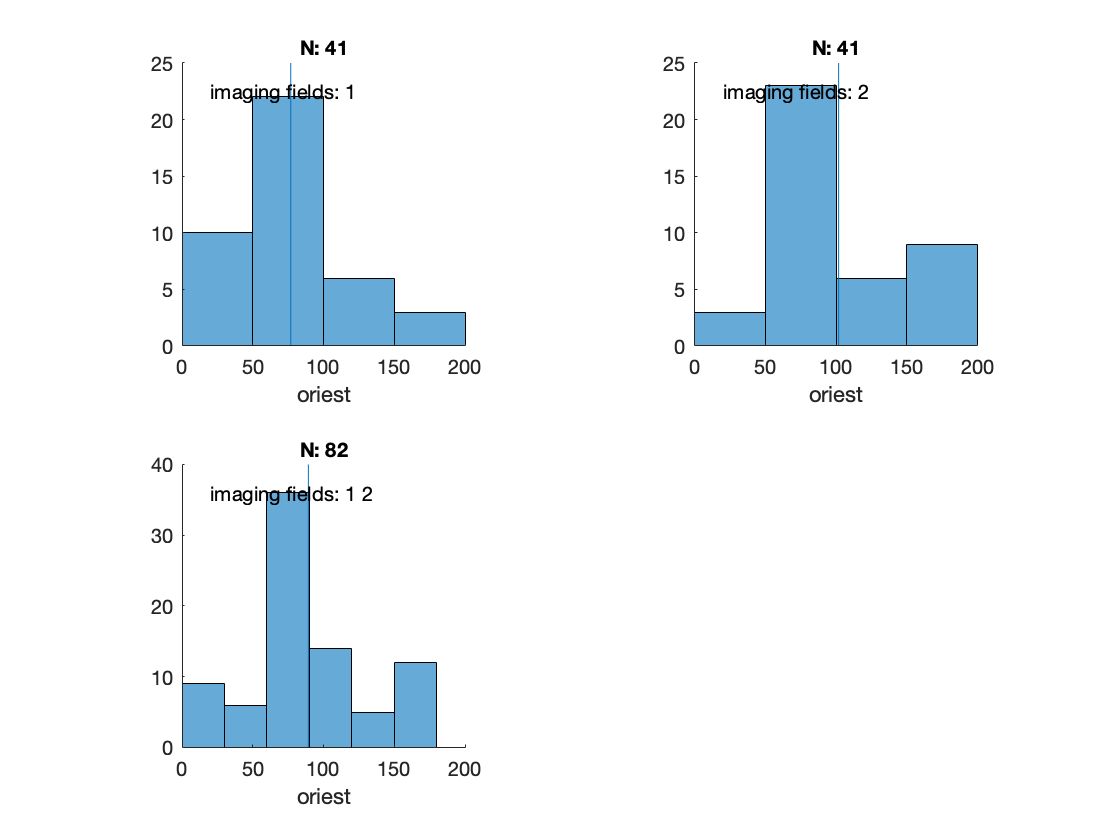

close all
variable_name = 'oriest';
main_requirement = logical(lgn.roi_stack.signif_tun);

uif1_roi_requirments = lgn.roi_stack.uniqImFieldNum == 1 & main_requirement;
tbl_uif1_of_single_rois = lgn.roi_stack(uif1_roi_requirments,:);
lgn.plot_univar_hist(tbl_uif1_of_single_rois, variable_name)

uif2_roi_requirments = lgn.roi_stack.uniqImFieldNum == 2 & main_requirement;
tbl_uif2_of_single_rois = lgn.roi_stack(uif2_roi_requirments,:);
lgn.plot_univar_hist(tbl_uif2_of_single_rois, variable_name)

uifALL_roi_requirments = main_requirement;
tbl_uifALL_of_single_rois = lgn.roi_stack(main_requirement,:);
lgn.plot_univar_hist(tbl_uifALL_of_single_rois, variable_name)

## Discussion

# Test whether populations of LGN boutons exhibit local tuning biases

## Generate a bouton-pair 'distance' data table

lgn.get_distance_table(); 
head(lgn.dist_stack)    

ans = 8×33 table
      mouse      uif    pair_roiDistMatIdx    pair_roiOrisfId    pair_roiHoughId    dRetKern_c2cDist    dRetKern_corr    dRetKern_corrStrong    dRetKern_corrWeak     dRetKern_Overlap     dRetKern_OverlapFiftyPrc    dRetKern_OverlapYes    dRetKern_OverlapNo      dTunKern_cos         dTunKern_corr            dSfResp              dLogSfEst         dLogSfEst_lessThanHalfOct    dLogSfEst_lessThanOneOct    dLogSfEst_lessThanTwoOct    dLogSfEst_lessThanThreeOct    dLogSfEst_AnyDiff    dLogSfEst_moreThanHalfOct    dLogSfEst_moreThanOneOct    dLogSfEst_moreThanTwoOct

tail(lgn.dist_stack)

ans = 8×33 table
      mouse      uif    pair_roiDistMatIdx    pair_roiOrisfId    pair_roiHoughId    dRetKern_c2cDist     dRetKern_corr    dRetKern_corrStrong    dRetKern_corrWeak     dRetKern_Overlap     dRetKern_OverlapFiftyPrc    dRetKern_OverlapYes    dRetKern_OverlapNo      dTunKern_cos         dTunKern_corr            dSfResp              dLogSfEst         dLogSfEst_lessThanHalfOct    dLogSfEst_lessThanOneOct    dLogSfEst_lessThanTwoOct    dLogSfEst_lessThanThreeOct    dLogSfEst_AnyDiff    dLogSfEst_moreThanHalfOct    dLogSfEst_moreThanOneOct    dLogSfEst_moreThanTwoOct</

Now you have a distance table

- each row corresponds to a pair of LGN boutons in some imaging field

- columns correspond to some property of that bouton pair (receptive field overlap, similarity of tuning kernel, etc)

## Model the relationship between tuning similarity and RF overlap, for pairs of boutons in one imaging field

Fit a linear Model and Run a Rank sum test for one population of LGN boutons

clf;
uif  = lgn.roi_stack_uif_list(1);
lgn.fit_plot_lm(uif);


Run it again but this time with all pairs of boutons, accross all imaging fields

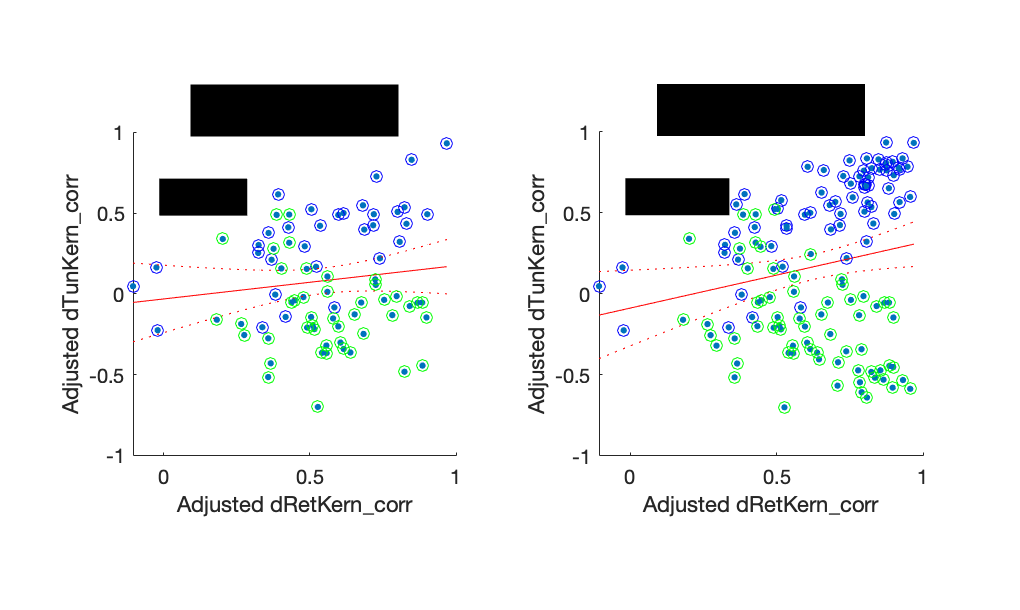

uif_stack   = lgn.roi_stack_uif_list;
lgn.fit_plot_lm(uif_stack);

## Discussion